if ~isfolder('kmeans')
    mkdir('kmeans');
end

% Get a list of image files and mask files in their respective folders
imageFiles = dir('input/*');
numImages = numel(imageFiles)

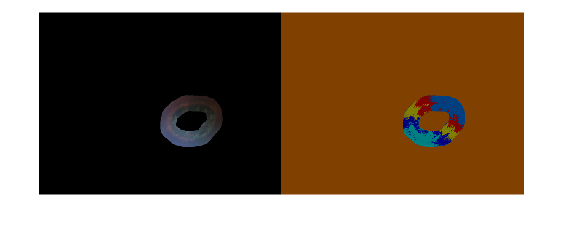

for i = 3:numImages
    imagefolder = fullfile('input',imageFiles(i).name);
    imagefiles = dir(fullfile('input',imageFiles(i).name,'onion_img_*'));

    outputFolder = fullfile('kmeans', imageFiles(i).name);
    if ~isfolder(outputFolder)
        mkdir(outputFolder);
    end

    imagefile = fullfile(imagefolder,imagefiles.name);
    image = imread(imagefile);
    
    LAB = rgb2lab(image);
    L = LAB(:,:,1)/100;
    L = adapthisteq(L,'NumTiles',[8 8],'ClipLimit',0.005);
    
    LAB(:,:,1) = L*100;
    mm = lab2rgb(LAB);
    
    mm = uint16(mm);
    
    % imshow(mm)
    
    L = imsegkmeans(image,6);
    B = labeloverlay(mm,L);
    imshow(B)

    mon = montage({image,B});
    % Extract pixel data from the montage image
    montage_data = mon.CData;

    % Save the original image in the current image's folder
    imwrite(image, fullfile(outputFolder, ['orig_', imageFiles(i).name, '.jpg']));

    % Save kmeans image in the current image's folder
    imwrite(B, fullfile(outputFolder, ['kmeans_', imageFiles(i).name, '.jpg']));

    % Save montage image in the current image's folder
    imwrite(montage_data, fullfile(outputFolder, ['montage_', imageFiles(i).name, '.jpg']));

end